Rdata = csvread('C:\Users\ZIN\Documents\GitHub\predict_blood_glucose\scv\train01.csv',1,0);
data = Rdata'

data =   165.2400  164.5300  163.8200  163.1200  162.4200  161.7300  161.0400  160.3600  159.6900  159.0200  158.3600  157.7000  157.0500  156.4000  155.7600  155.1200  154.4900  153.8700  153.2500  152.6400  152.0300  151.4300  150.8300  150.2400  149.6500  149.0700  148.5000  147.9300  147.3600  146.8000  146.2500  145.7000  145.1600  144.6200  144.0900  143.5600  143.0400  142.5200  142.0100  141.5100  141.0100  140.5100  140.0200  139.5300  139.0500  138.5800  138.1100  137.6400  137.1800  136.7200
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

% plot(data')
%읽은 csv출력
num=numel(data);
n=60;
indexLength=750;
% 어느정도의 미래까지 예측할지에 사용되는 변수 간격이 5분이라면 5n분 후까지 예측

[layers,options] = InitialOption();
% %LSTM의 초기값 설정
% 
 
[net,mu,sig,YTrainend]=trainning(data(1:indexLength),layers,options);
% 
% 
%[YPred] = Predict1(net,n,YTrainend);
% YPred = Destandard(YPred, mu, sig);
% Rmse(YPred,data(indexLength+1:indexLength+n));
% Dataplot(data(1:indexLength+n),YPred,n)

[YPred] = Predict2(net,n,Standard(data(indexLength:indexLength+n-1),mu,sig));
YPred = Destandard(YPred, mu, sig);
Rmse(YPred,data(indexLength+1:indexLength+n));

rmse = 3.7343

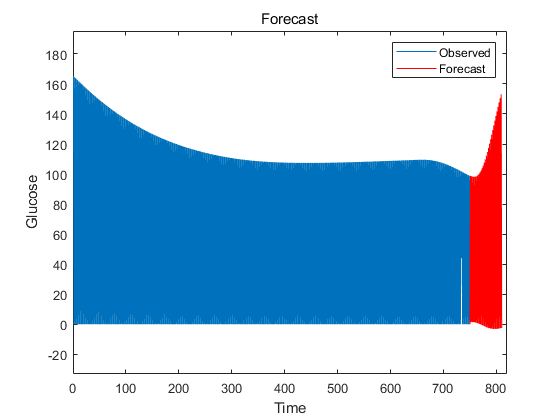

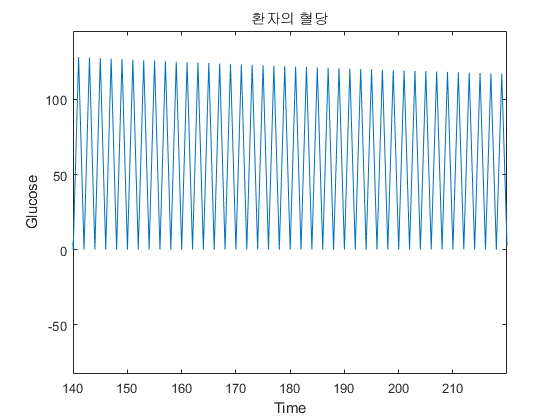

Dataplot(data(1:indexLength+n),YPred,n)

 
count = n

count = 60


% while(true)           
%     prompt = '5 minutes later?';
%     x = input(prompt,'s');
%     %Enter을 누를때마다 5분이 지났음을 의미
%     if strcmp(x,'end')
%         break
%     elseif((indexLength+count)>=num)
%         break
%     end
%     [YPred(count+1)] = Predict2(net,1,Standard(data(indexLength+count),mu,sig));
%     count = count + 1 
%     
% end   
% ccount =count;
% k="end of real data";
% YPred(n+1:count) = Destandard(YPred(n+1:count), mu, sig);
% Rmse(YPred,data(indexLength+1:indexLength+count));
% Dataplot(data(1:indexLength+count),YPred,count)

% while(true)      
%     prompt = '5 minutes later?';
%     x = input(prompt,'s');
%     %Enter을 누를때마다 5분이 지났음을 의미
%     if strcmp(x,'end')
%         break
%     end
%     [YPred(count+1)] = Predict2(net,1,Standard(YPred(end),mu,sig));
%     count = count + 1 
% end 
% YPred(ccount+1:count) = Destandard(YPred(ccount+1:count), mu, sig);
% Rmse(YPred,data(indexLength+1:indexLength+count));
% plot([data(1:indexLength) YPred])
% 



function [YPred] = Predict1(net,n,YTrain)
    YPred = zeros(1,n);
    [net,YPred] = predictAndUpdateState(net,YTrain);
    for Num = 2:n   
         [net,YPred(Num)] = predictAndUpdateState(net,YPred(Num-1)); 
    end    
end
function [YPred] = Predict2(net,n,realData)
    YPred = zeros(1,n);
    for Num = 1:n   
         [net,YPred(Num)] = predictAndUpdateState(net,realData(Num)); 
    end    
end
function [StandardizedData, mu, sig] = Standard(data,mu,sig)
    if (mu == 0)
        mu = mean(data);
    end  
    if (sig ==0)
        sig = std(data);
    end
    %표준화를 위해 학습용 데이터들에 대한 평균과 표쥰편차 할당
    
    StandardizedData = (data - mu)/ sig;
    %데이터의 평균과 표준편차를 통해 표준화 수행
end


function DestandardizedData = Destandard(data, mu, sig)
    DestandardizedData = sig*data + mu;
    %표준화 해제
end

function rmse = Rmse(YPred,real,n)
    rmse = sqrt(mean((YPred-real).^2))
end

function [net,mu,sig,YTrainend] = trainning(data,layers,options)  
    
    numTimeStepsTrain = floor(numel(data));
    dataTrain = data(1:numTimeStepsTrain);    
    [dataTrainStandardized, mu, sig] = Standard(dataTrain,0,0);    
         XTrain = dataTrainStandardized(1:end-1);
         YTrain = dataTrainStandardized(2:end);
         net = trainNetwork(XTrain,YTrain,layers,options);
         net = predictAndUpdateState(net,XTrain);
        YTrainend = YTrain(end);
end

function Dataplot(data,YPred,ntest)
    ntrain = numel(data);
    ntrain =ntrain -ntest;         
    dataTrain = data(1:ntrain);
 
    idx = ntrain:(ntrain+ntest);
    figure
    plot(dataTrain(1:end))
    %학습데이터를 그래프로 표시
    hold on
    %새로운 그래프를 추가하고 기존 그래프에 통합
    plot(idx,[data(ntrain) YPred],'r-')
    %예측된 데이터를 그래프로 표현
    hold off
    xlabel("Time")
    ylabel("Glucose")
    title("Forecast")
    if(max(YPred)>max(data))
        M = max(YPred);
    else
        M = max(data);
    end
    
    if(min(YPred)>min(data))
        m = min(data);
    else
        m = min(YPred);
    end
    
    ntrain = ntrain+ntest;
     xlim([0,ntrain+10]) %      xlim([ntrain-ntest-10,ntrain+10])
      ylim([m-30,M+30])
    legend(["Observed" "Forecast"])
    
    figure
    plot(data')
    xlabel("Time")
    ylabel("Glucose")
    title("환자의 혈당") 
    xlim([ntrain-ntest-10,ntrain+10]) 
    ylim([m-30,M+30])
end

function [layers,options] = InitialOption()
numFeatures = 1;
numResponses = 1;
numHiddenUnits = 150;
%은닉계층을 150개로 설정

layers = [
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];
    %입력 및 응답레이어를 각각 1개로 설정하고 200개의 은닉계층을 갖는 선형 레이어 구성

options = trainingOptions('adam',... %adam경사하강법 채택
    'MaxEpochs', 250, ... % 250회 반복
    'GradientThreshold', 1, ... %기울기 임계값 설정
    'InitialLearnRate', 0.005, ...  %초기 학습률
    'LearnRateSchedule', 'piecewise', ... 
    'LearnRateDropPeriod', 125,... %125회마다 학습률 변화
    'LearnRateDropFactor', 0.2, ...%0.2만큼 학습률 감소
    'Verbose', 0);%,'plots','training-progress'); %학습과정에 대한 그래프 표시
end

